# Pd-membrane WGS reactor model: interactive walkthrough

1D steady model of a Pd membrane inside a packed water-gas shift bed (PhD project, EBRI, Aston University). Run one section at a time (Ctrl+Enter). Change the values at the top of a section and run it again. For a slider or drop-down, right-click a number or text value in the Live Editor and choose Add Control. All results are unvalidated model predictions; the last section lists the main limits.

## 1. Setup

Adds the model folders to the path and reads the parameter register (every value has a source and a kind).

setup_paths

pbmr1d (MATLAB) paths added: C:\Users\250549557\Documents\GitHub\Membrane-Reactor-Modelling\matlab


p = load_params;

## 2. How the model was designed

Question first: for high-CO feeds (25-50 % CO, 300-470 C, 4-5 bar), which mechanism limits performance along the bed, and how does that change with conditions?

- The model computes reaction, H2 permeation and heat removal side by side at every position.

- "Limiting" is defined before any result exists: each position gets a regime label (section 10).

- Plug flow, steady state, ideal gas. Balances for six species, the H2 in the permeate stream, temperature and pressure. Back-permeation is allowed only with a sweep gas (switch in section 9).

- Every physical effect is its own function, so a rate law or membrane can be swapped without touching the reactor code.

- Every number lives in one register with a source and a kind. The reactor code contains no numbers.

- Checked against limits that can be worked out by hand, against an independent Python model, and by a 385-check run over varied conditions (tests/run_verification).

## 3. Architecture

Each layer uses only the layers above it.

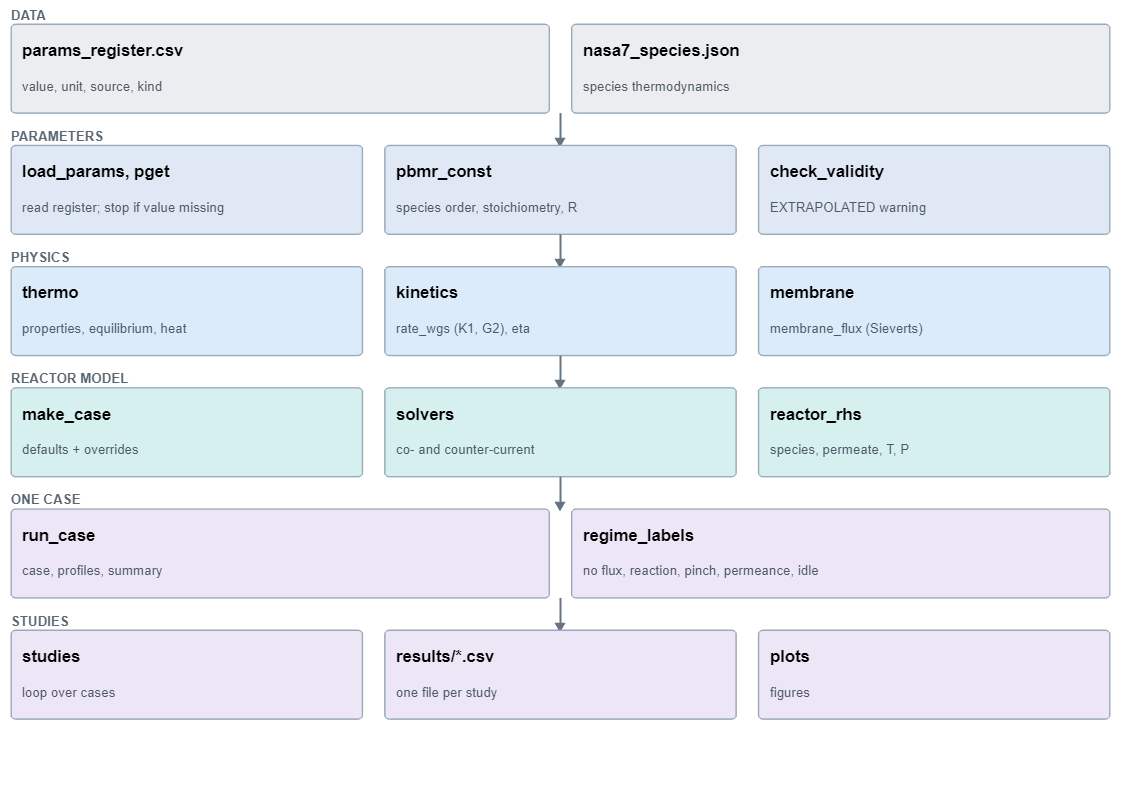

plot_architecture

## 4. Where the parameters came from

Open literature only. No H2Site rig data are used. Each row of the register has a kind: reported (read from a paper), inferred, assumed, placeholder (value missing), sweep (bounds), range (validity window).

f = fullfile(fileparts(which('load_params')), '..', '..', 'data', 'params_register.csv');
opts = detectImportOptions(f, 'Delimiter', ',', 'TextType', 'string');
opts = setvartype(opts, opts.VariableNames, 'string');
reg = readtable(f, opts);
kind = categorical(reg.kind);
kind = removecats(kind(kind ~= 'meta'));     % meta rows are labels and notes, not parameters
counts = countcats(kind);
table(string(categories(kind)), counts, 'VariableNames', {'kind', 'rows'})

ans = 6×2 table
        kind         rows
    _____________    ____

    "assumed"         10 
    "inferred"         1 
    "placeholder"      6 
    "range"           21 
    "reported"        73 
    "sweep"            6 


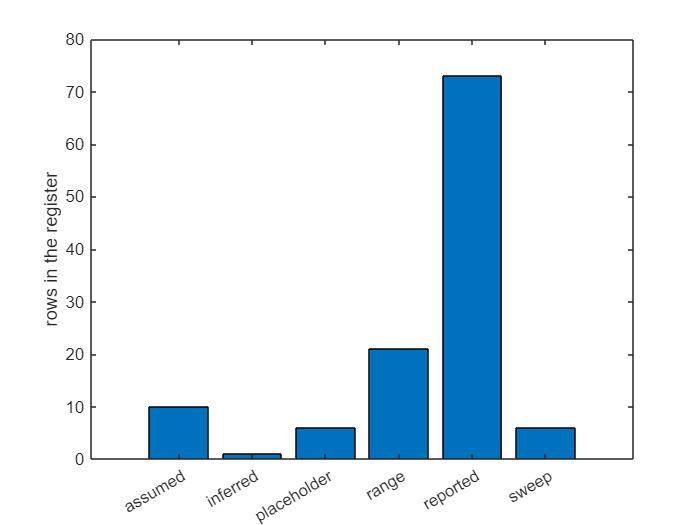

figure
bar(counts), xticklabels(categories(kind)), ylabel('rows in the register')

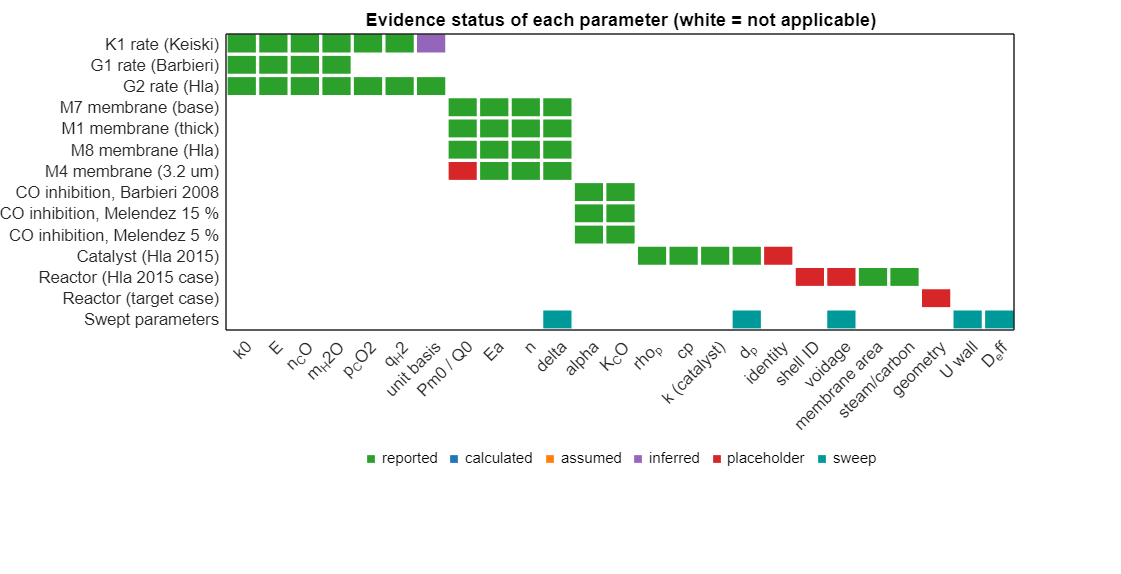

% Which parameter of which model block is reported, inferred, assumed or missing.
plot_evidence_matrix(p)

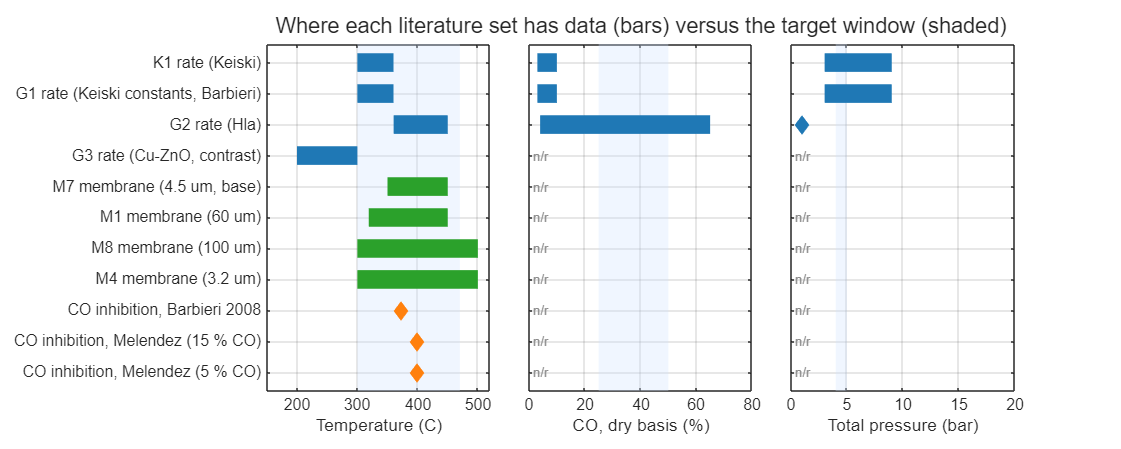

Fraction of the target window covered by each set (NaN = no range recorded):
                                         T_cover    yCO_cover    P_cover
                                         _______    _________    _______

    rate.K1                              0.35206         0           1  
    rate.G1                              0.35206         0           1  
    rate.G2                              0.52941         1           0  
    rate.G3                                    0       NaN         NaN  
    membrane.M7                          0.58824       NaN         NaN  
    membrane.M1                          0.77059       NaN         NaN  
    membrane.M8                                1       NaN         NaN  
    membrane.M4                     

% Data range of each literature parameter set against the target window (300-470 C, 25-50 % CO, 4-5 bar).
plot_validity_window(p);

## 5. Main sources

Where the important values come from, as recorded in the register and the design document.

table(["Membrane M7 (base)"; "Membrane M1 (thick contrast)"; "Rate law K1"; "Rate law G2"; ...
    "Equilibrium constant"; "Catalyst density, cp, k"; "Bed geometry"; "Wall U, voidage, D_eff"], ...
    ["Helmi 2017, 4.5 um; data at 1.2-1.6 bar, so extrapolated to 4-5 bar"; ...
    "Barbieri 2008, 60 um"; ...
    "Keiski 1996; concentration basis inferred, because the printed units give an impossible rate"; ...
    "Hla 2009 constants (HTC2), pressure in kPa as printed; fitted at about 1 bar, 360-450 C"; ...
    "NASA polynomials (GRI-Mech 3.0 via Cantera), checked against Moe 1962"; ...
    "Hla 2015, for one catalyst"; ...
    "Template from Hla 2015; shell diameter assumed 1 in"; ...
    "No source in the papers: assumed and swept"], ...
    'VariableNames', {'item', 'source'})

ans = 8×2 table
                 item                                                             source                                            
    ______________________________    ______________________________________________________________________________________________

    "Membrane M7 (base)"              "Helmi 2017, 4.5 um; data at 1.2-1.6 bar, so extrapolated to 4-5 bar"                         
    "Membrane M1 (thick contrast)"    "Barbieri 2008, 60 um"                                                                        
    "Rate law K1"                     "Keiski 1996; concentration basis inferred, because the printed units give an impossible rate"
    "Rate law G2"                     "Hla 2009 constants (HTC2), pressure in kPa as printed; fitted at about 1 bar, 360-450 C"     
    "Equilibrium constant"            "NASA polynomials (GRI-Mech 3.0 via Cantera), checked against Moe 1962"        

## 6. Which function reads which parameter

Built by scanning the code for pget calls, so it always matches what the functions really read. A key such as rate.<law>.n_CO depends on the option chosen (law = K1 or G2).

usage = param_usage(p);
which_function = "rate_wgs";          % try membrane_flux, make_case
usage(usage.func == which_function, {'key', 'kind'})

ans = 14×2 table
               key                  kind    
    _________________________    ___________

    "catalyst.Hla2015.rho_p"     "reported" 
    "rate.<law>.n_CO"            "by option"
    "rate.G2.E"                  "reported" 
    "rate.G2.log10_k0"           "reported" 
    "rate.G2.m_H2O"              "reported" 
    "rate.G2.n_CO"               "reported" 
    "rate.G2.p_CO2"              "reported" 
    "rate.G2.pressure_unit"      "reported" 
    "rate.G2.q_H2"               "reported" 
    "rate.K1.E"                  "reported" 
    "rate.K1.conc_basis_used"    "inferred" 
    "rate.K1.ln_k0"              "reported" 
    "rate.K1.m_H2O"              "reported" 
    "rate.K1.n_CO"               "reported" 


## 7. How the parameters relate to each other

Links recorded in the register: reuses, conflicts_with, needs, inferred_from, range_from, maybe_affected_by.

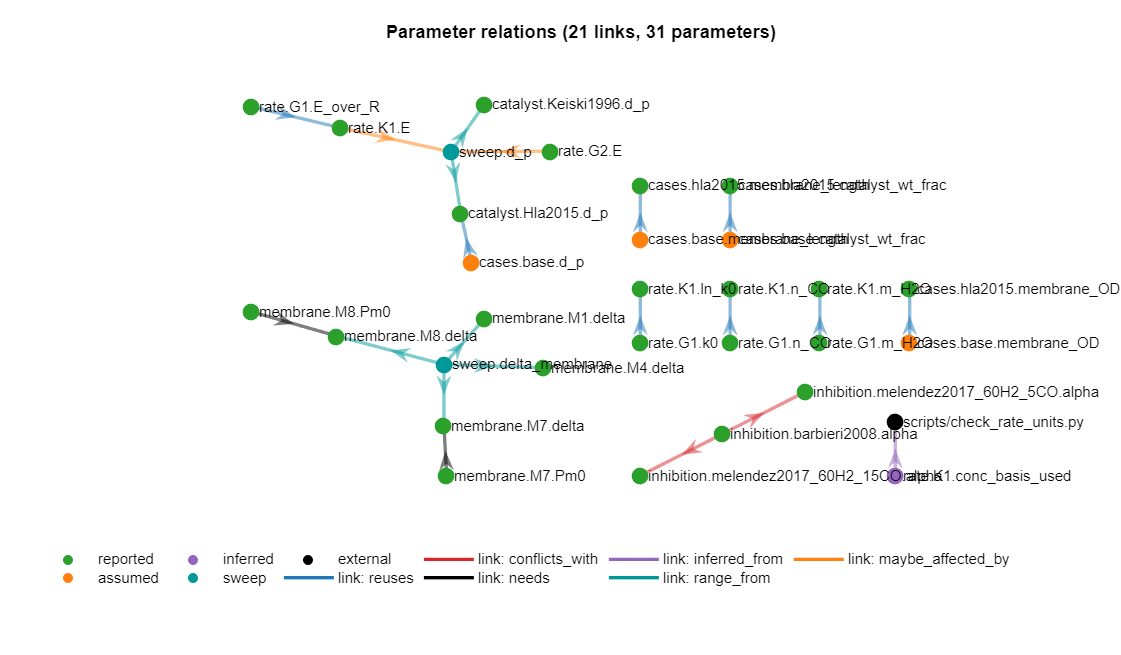

plot_param_relations(p)

## 8. Base case

40 % CO (dry), steam-to-CO 3, 400 C inlet, 4.5 bar, membrane M7 (4.5 um), permeate 1.01 bar, no sweep gas.

out = run_case(p);
sm = out.summary;
table(sm.X_CO, sm.H2_recovery, sm.T_out, sm.atom_error, ...
    'VariableNames', {'X_CO', 'H2_recovery', 'T_out_K', 'atom_error'})

ans = 1×4 table
     X_CO      H2_recovery    T_out_K    atom_error
    _______    ___________    _______    __________

    0.94272      0.39119      673.15     5.421e-16 


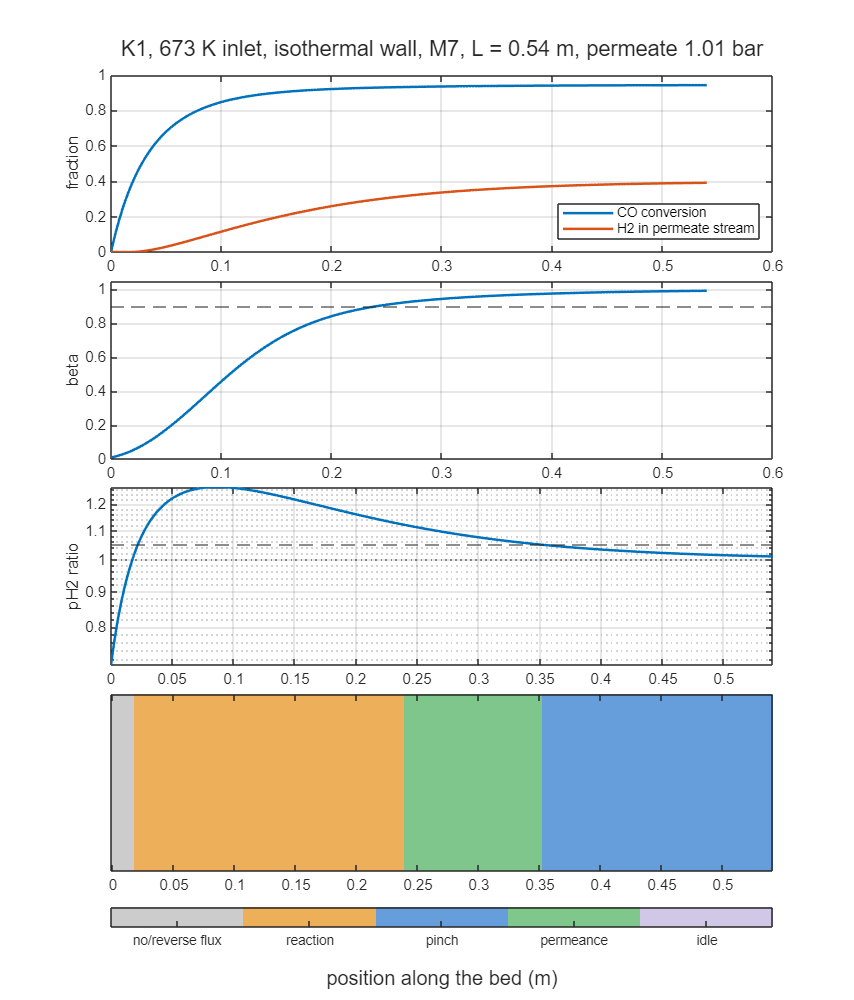

plot_case_profile(out)

## 9. Your own case

Edit these values and rerun. Counter-current only differs from co-current when sweep > 0.

membrane = 'M7';          % M7 (4.5 um) or M1 (60 um)
T_in = 673.15;            % inlet temperature, K
bed_length = 0.54;        % m
P_perm_bar = 1.01325;     % permeate pressure, bar
sweep_mmol_s = 1;         % inert sweep gas on the permeate side, mmol/s
backperm = 'on';          % on or off: let H2 flow back into the retentate if the permeate side has the higher pressure (needs a sweep)
flow = 'counter';         % cocurrent or counter
rate_law = 'K1';          % K1 or G2
wall = 'isothermal';      % isothermal or adiabatic

ov = struct('membrane', membrane, 'T_in', T_in, 'L', bed_length, 'P_perm', P_perm_bar * 1e5, ...
    'sweep', sweep_mmol_s * 1e-3, 'backperm', backperm, 'flow', flow, 'law', rate_law, 'wall', wall);
out = run_case(p, ov);
sm = out.summary;
table(sm.X_CO, sm.X_eq, sm.H2_recovery, sm.permeate_H2_fraction, sm.T_out, ...
    'VariableNames', {'X_CO', 'X_eq_no_membrane', 'H2_recovery', 'H2_share_of_permeate', 'T_out_K'})

ans = 1×5 table
     X_CO      X_eq_no_membrane    H2_recovery    H2_share_of_permeate    T_out_K
    _______    ________________    ___________    ____________________    _______

    0.99997        0.91014           0.99999            0.42857           673.15 


disp(sm.flags')

    {'EXTRAPOLATED (membrane M7): dP bar outside data range [1.2, 1.6]'}
    {'EXTRAPOLATED: CO dry - outside data range [0.03, 0.1]'           }
    {'EXTRAPOLATED: T K outside data range [573, 633]'                 }



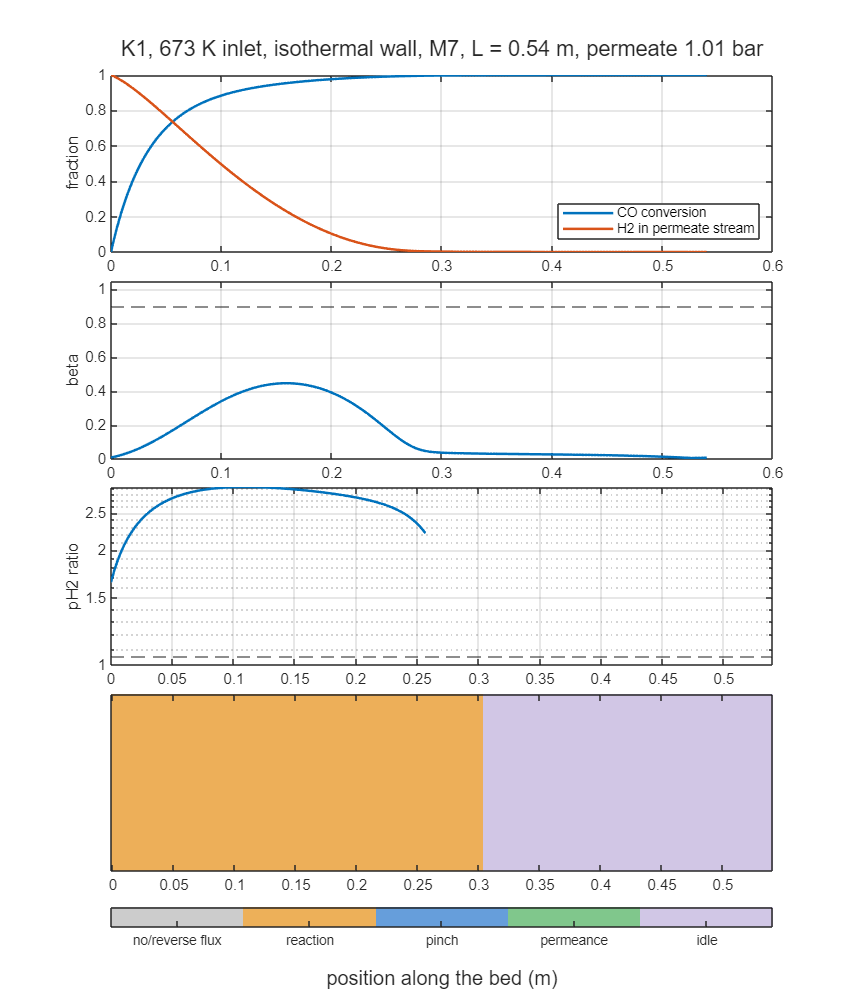

plot_case_profile(out)

## 10. Which mechanism limits, and where?

Share of the bed length in each regime for the case above. no/reverse flux: membrane not passing H2, or H2 would flow back (only with a sweep). reaction: far from equilibrium. pinch: no H2 driving force left. permeance: membrane is the limit. idle: reaction and flux both negligible. The thresholds (beta 0.9, 5 %, 1 %) are proposals, not findings.

figure
bar(categorical(sm.regime_names, sm.regime_names), 100 * sm.regime_fraction)
ylabel('share of bed length (%)')

## 11. Co-current against counter-current

Same case and sweep, both directions.

sweep_compare_mmol_s = 1;
cmp = rmfield(ov, {'flow', 'sweep'});
cmp.sweep = sweep_compare_mmol_s * 1e-3;
plot_flow_compare(p, cmp)

## 12. Sweep gas: recovery against permeate purity

More sweep raises recovery but dilutes the permeate that would go to the SOFC.

sweeps = [0.5 1 2 5];
flows = {'cocurrent', 'counter'};
recovery = zeros(2, numel(sweeps));
share = zeros(2, numel(sweeps));
for i = 1:2
    for k = 1:numel(sweeps)
        o = rmfield(ov, {'flow', 'sweep'});
        o.flow = flows{i};
        o.sweep = sweeps(k) * 1e-3;
        s = run_case(p, o).summary;
        recovery(i, k) = s.H2_recovery;
        share(i, k) = s.permeate_H2_fraction;
    end
end
figure('Position', [100 100 800 340]);
tiledlayout(1, 2)
nexttile
plot(sweeps, recovery', '-o'), grid on
xlabel('sweep gas (mmol/s)'), ylabel('H2 recovery'), legend(flows, 'Location', 'southeast')
nexttile
plot(sweeps, share', '-o'), grid on
xlabel('sweep gas (mmol/s)'), ylabel('H2 share of permeate')

## 13. Where a number comes from

Each parameter carries a value, unit, source and kind.

key = 'cases.base.bed_voidage';      % try 'membrane.M7.Pm0' or 'cases.base.T_in'
leaf = p;
for part = strsplit(key, '.')
    leaf = leaf.(part{1});
end
leaf

% Main limits of the model
%
% - Membrane M7 flux is extrapolated from 1.2-1.6 bar data to 4-5 bar.
%
% - K1: the concentration basis is inferred (printed units give a rate about 1e5 times too high), checked only against the Hla law.
%
% - G2: units are as printed (Hla 2009), but the fit was made near 1 bar and 360-450 C, so 4-5 bar is an extrapolation.
%
% - Both laws are used outside their fitted windows.
%
% - Counter-current recoveries close to 100 % are upper bounds: ideal pure-H2 permeate, no polarisation, inert sweep.
%
% - Wall heat transfer, bed voidage and effective diffusivity are assumed.
%
% - Concentration polarisation (H3) is not in this 1D model; it is for the 2D CFD model.
%
% - Nothing here is validated against rig data yet.